%% MFC4 PROJECT: Spectral Clustering based on the Graph p-Laplacian
% TEAM MEMBERS: Koushik, Rohith Kumar, Rohith Kanna, G. Vishal (Group D-16)
% REFERENCE: T. Bühler and M. Hein (ICML 2009)
% =========================================================================

clear; clc; close all;
tic
%% ========================================================================
%  DATASET 1: THE TWO MOONS
%  ========================================================================
disp('================================================');

disp('RUNNING DATASET 1: TWO MOONS...');

RUNNING DATASET 1: TWO MOONS...



n_samples = 500;
noise_level = 0.1;

n1 = floor(n_samples/2); n2 = n_samples - n1;
t1 = linspace(0, pi, n1)'; t2 = linspace(0, pi, n2)';
x1 = [cos(t1), sin(t1)];
x2 = [1 - cos(t2), 1 - sin(t2) - 0.5];
X_moons = [x1; x2] + noise_level * randn(n_samples, 2);
y_true_moons = [ones(n1, 1); 2*ones(n2, 1)];

% Run Moons
[v2_moons, f_final_moons, acc_moons] = run_p_spectral(X_moons, y_true_moons, 10, 0.1);
fprintf(' -> Two Moons Final Accuracy: %.2f%%\n', acc_moons);

 -> Two Moons Final Accuracy: 99.60%


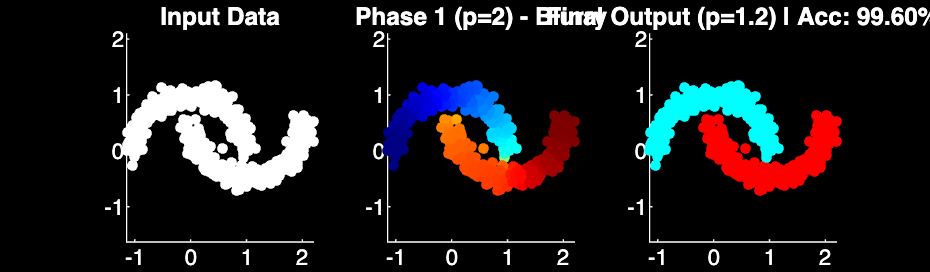


% Plot Moons
fig1 = figure('Name', 'Dataset 1: Two Moons', 'Position', [100, 500, 1200, 350], 'Color', 'k');
subplot(1,3,1); scatter(X_moons(:,1), X_moons(:,2), 15, 'w', 'filled'); 
set(gca, 'Color', 'k', 'XColor', 'w', 'YColor', 'w'); title('Input Data', 'Color', 'w'); axis equal;

subplot(1,3,2); scatter(X_moons(:,1), X_moons(:,2), 15, v2_moons, 'filled'); colormap(jet); 
set(gca, 'Color', 'k', 'XColor', 'w', 'YColor', 'w'); title('Phase 1 (p=2) - Blurry', 'Color', 'w'); axis equal;

subplot(1,3,3); idx1 = f_final_moons > 0; idx2 = f_final_moons <= 0;
hold on; scatter(X_moons(idx1,1), X_moons(idx1,2), 15, 'r', 'filled'); scatter(X_moons(idx2,1), X_moons(idx2,2), 15, 'c', 'filled'); hold off;
set(gca, 'Color', 'k', 'XColor', 'w', 'YColor', 'w'); title(sprintf('Final Output (p=1.2) | Acc: %.2f%%', acc_moons), 'Color', 'w'); axis equal;



%% ========================================================================
%  DATASET 2: CONCENTRIC CIRCLES (BULLSEYE)
%  ========================================================================
disp(' ');

disp('RUNNING DATASET 2: CONCENTRIC CIRCLES...');

RUNNING DATASET 2: CONCENTRIC CIRCLES...



n_outer = 250; n_inner = 250;
t1_circ = linspace(0, 2*pi, n_outer)'; t2_circ = linspace(0, 2*pi, n_inner)';
r_out = 1.0 + 0.05 * randn(n_outer, 1); r_in  = 0.4 + 0.05 * randn(n_inner, 1);
X_circles = [r_out.*cos(t1_circ), r_out.*sin(t1_circ); r_in.*cos(t2_circ), r_in.*sin(t2_circ)];
y_true_circles = [ones(n_outer, 1); 2*ones(n_inner, 1)];

% Run Circles with perfect graph parameters (k=10, sigma=0.1)
[v2_circles, f_final_circles, acc_circles] = run_p_spectral(X_circles, y_true_circles, 10, 0.1);
fprintf(' -> Concentric Circles Final Accuracy: %.2f%%\n', acc_circles);

 -> Concentric Circles Final Accuracy: 100.00%


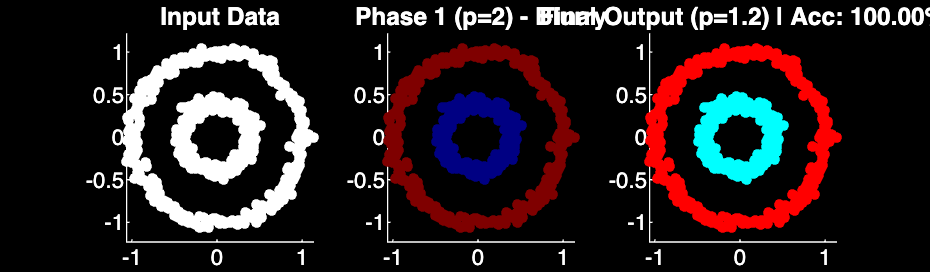


% Plot Circles
fig2 = figure('Name', 'Dataset 2: Concentric Circles', 'Position', [100, 100, 1200, 350], 'Color', 'k');
subplot(1,3,1); scatter(X_circles(:,1), X_circles(:,2), 15, 'w', 'filled'); 
set(gca, 'Color', 'k', 'XColor', 'w', 'YColor', 'w'); title('Input Data', 'Color', 'w'); axis equal;

subplot(1,3,2); scatter(X_circles(:,1), X_circles(:,2), 15, v2_circles, 'filled'); colormap(jet); 
set(gca, 'Color', 'k', 'XColor', 'w', 'YColor', 'w'); title('Phase 1 (p=2) - Blurry', 'Color', 'w'); axis equal;

subplot(1,3,3); idx1 = f_final_circles > 0; idx2 = f_final_circles <= 0;
hold on; scatter(X_circles(idx1,1), X_circles(idx1,2), 15, 'r', 'filled'); scatter(X_circles(idx2,1), X_circles(idx2,2), 15, 'c', 'filled'); hold off;
set(gca, 'Color', 'k', 'XColor', 'w', 'YColor', 'w'); title(sprintf('Final Output (p=1.2) | Acc: %.2f%%', acc_circles), 'Color', 'w'); axis equal;


disp('================================================');

disp('PROJECT EXECUTION FINISHED.');

PROJECT EXECUTION FINISHED.




%% ========================================================================
%  LOCAL FUNCTION: THE P-SPECTRAL ALGORITHM ENGINE
%  ========================================================================
function [v2, f, accuracy] = run_p_spectral(X, y_true, k, sigma)
    N = size(X, 1);
    
    % --- GRAPH CONSTRUCTION (k-NN) ---
    D_sq = pdist2(X, X, 'squaredeuclidean');
    [~, sort_idx] = sort(D_sq, 2);
    W = zeros(N);
    for i = 1:N
        neighbors = sort_idx(i, 2:k+1);
        W(i, neighbors) = exp(-D_sq(i, neighbors) / (2 * sigma^2));
        W(neighbors, i) = W(i, neighbors)';
    end
    
    % --- PHASE 1 (Standard Spectral) ---
    D_mat = diag(sum(W, 2)) + 1e-10 * eye(N); 
    L = D_mat - W;
    [V, ~] = eigs(L, D_mat, 2, 'sm');
    
    v2 = V(:, 2);
    v2 = v2 - mean(v2); % Center the values
    
    % --- PHASE 2 (p-Laplacian Optimization) ---
    p_seq = [1.8, 1.6, 1.4, 1.2];
    f = v2; 
    lr = 0.01;
    
    for p = p_seq
        for iter = 1:40
            grad = zeros(N, 1);
            for i = 1:N
                diff = f(i) - f;
                weights = W(i, :)' .* (abs(diff) + 1e-6).^(p-2);
                grad(i) = sum(weights .* diff);
            end
            f = f - lr * grad;
            f = f - mean(f); 
            f = f / norm(f);
        end
    end
    
    % --- ACCURACY CALCULATION ---
    y_pred = (f > 0) + 1; 
    acc1 = sum(y_pred == y_true) / N * 100;
    acc2 = sum(y_pred ~= y_true) / N * 100;
    accuracy = max(acc1, acc2);
end
toc

Elapsed time is 7.108294 seconds.
